## **Bayesian Optimisation Example**

Goal: *maximise the function f(x) = x.*sin( x );  in the interval [0, 10]*

clear
close all
x = linspace( 0, 10, 501 ).';
f = x.*sin( x );


Extract 7 points for training an initial surrogate model & plot the results:

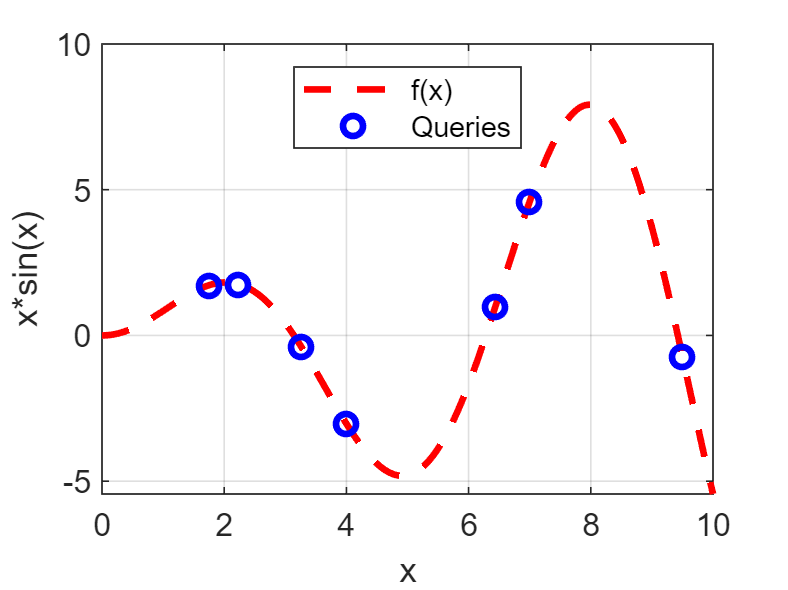

X = [ 9.5, 2.24, 4, 1.76, 3.26, 6.44, 7.0 ].';
Y = X .* sin( X );
plot( x, f, 'r--', X, Y, 'bo', 'LineWidth', 2 );
grid on
xlabel( "x" );
ylabel( "x*sin(x)" );
legend( "f(x)", "Queries", "Location", "north")

Train the initial GP regression model

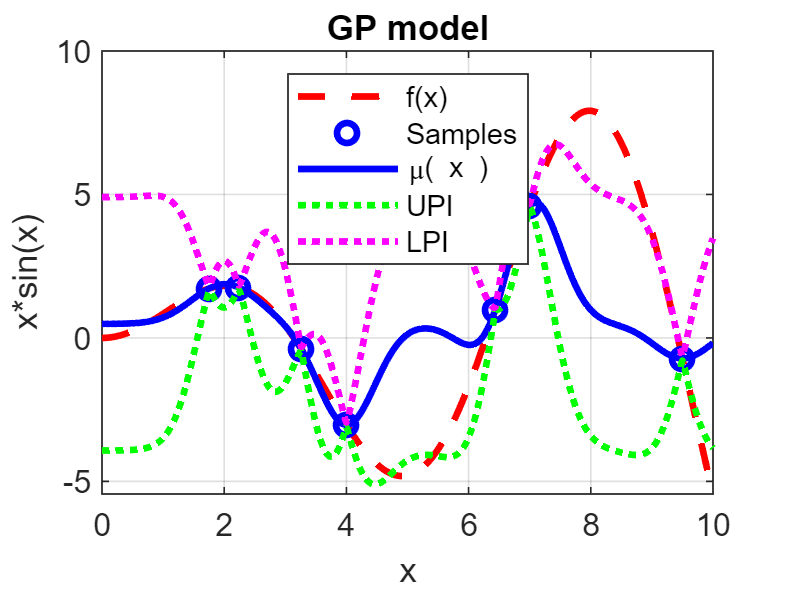

G = gpr( X, Y );
G = G.trainModel();
[ Yp, ~, Yint] = G.predict( x, 0.05 );
close all
figure;
plot(x, f, 'r--', X, Y, 'bo', x, Yp, 'b-', 'LineWidth', 2);
grid on
legend( "f(x)", "Samples", "\mu( x )", 'Location', 'north');
xlabel( "x" );
ylabel( "x*sin(x)" );
title( "GP model");
hold on;
plot(  x, Yint( :,1 ), 'g:', x, Yint( :,2 ), 'm:', 'LineWidth', 2);
legend( "f(x)", "Samples", "\mu( x )", "UPI", "LPI", 'Location', 'north');

Create an Upper Confidence Bound Acquisition Function object.

U = ucb( G );

Create a bayesian optimisation object and minimise UCB(x)

B = bayesOpt( U );
B = B.acqFcnMaxTemplate();

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       2   -4.604570e+00    0.000e+00    2.417e+00
    1      11   -4.782832e+00    0.000e+00    6.650e-02    1.250e-01
    2      13   -4.782919e+00    0.000e+00    1.449e-02    3.347e-03
    3      15   -4.782923e+00    0.000e+00    1.681e-05    5.987e-04
    4      17   -4.782923e+00    0.000e+00    5.858e-08    6.941e-07

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the 

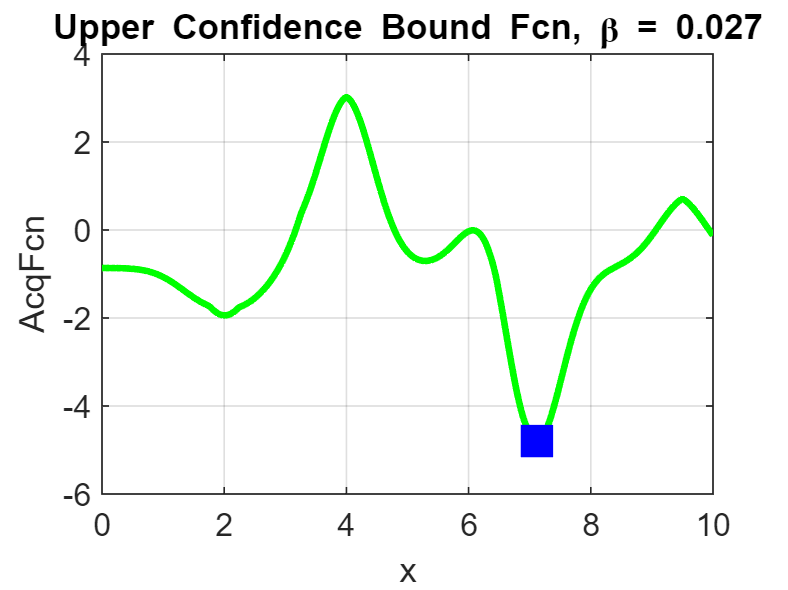

U = B.AcqObj;
figure;
A = U.evalFcn( x, U.Beta );
plot( x, A, 'g-', 'LineWidth', 2); grid on
xlabel( "x" )
ylabel( "AcqFcn" )
Tstr = sprintf( "Upper Confidence Bound Fcn, \\beta = %4.3f", U.Beta );
title( Tstr ); 
hold on, plot( B.Xnext, B.AcqObj.evalFcn( B.Xnext ), "bs", "MarkerSize", 12, "MarkerFaceColor", "blue" );
grid on
hold off

Query f(x) at the suggested value and update the GP model

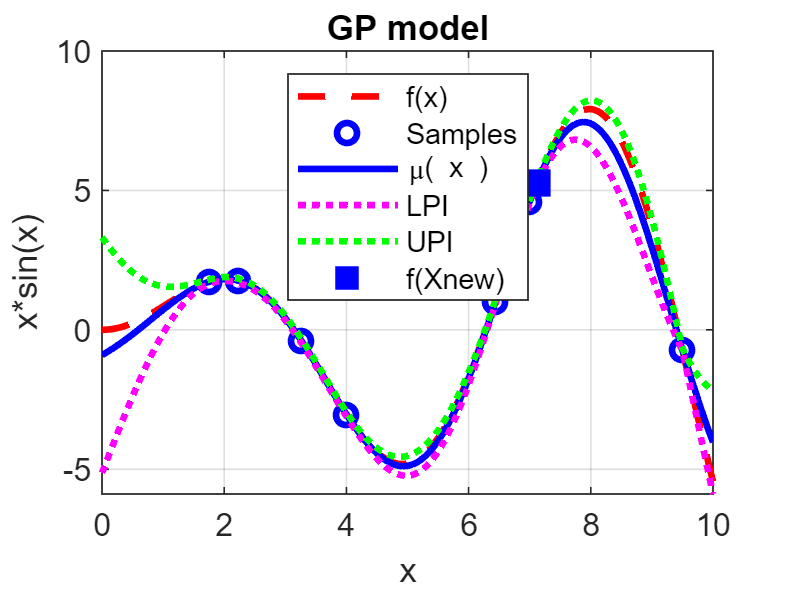

figure;
Xnew = B.Xnext;
Ynew = Xnew * sin( Xnew );
B = B.addNewQuery( Xnew, Ynew );
[ Yp, ~, Yint ] = B.ModelObj.predict( x );
plot(x, f, 'r--', X, Y, 'bo', x, Yp, 'b-', x, Yint( :,1 ), 'm:',...
    x, Yint( :,2 ), 'g:',  'LineWidth', 2);
hold on
plot( Xnew, Ynew, 'bs', 'MarkerSize', 10, 'MarkerFaceColor', 'blue');
grid on
legend( "f(x)", "Samples", "\mu( x )", "LPI", "UPI", "f(Xnew)", 'Location', 'north');
xlabel( "x" );
ylabel( "x*sin(x)" );
title( "GP model");

Now re-potimise the acquisition function

B = B.acqFcnMaxTemplate();

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       2   -5.297248e+00    0.000e+00    5.284e+00
    1       6   -6.360857e+00    0.000e+00    4.258e+00    1.321e+00
    2       8   -7.536894e+00    0.000e+00    3.799e-01    5.895e-01
    3      10   -7.545746e+00    0.000e+00    1.365e-02    4.829e-02
    4      12   -7.545757e+00    0.000e+00    3.667e-05    1.674e-03
    5      14   -7.545757e+00    0.000e+00    1.109e-06    4.487e-06
    6      18   -7.545757e+00    0.000e+00    2.029e-06    3.293e-08
    7      24   -7.545757e+00    0.000e+00    2.452e-06    6.586e-08

Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the <a href = "m

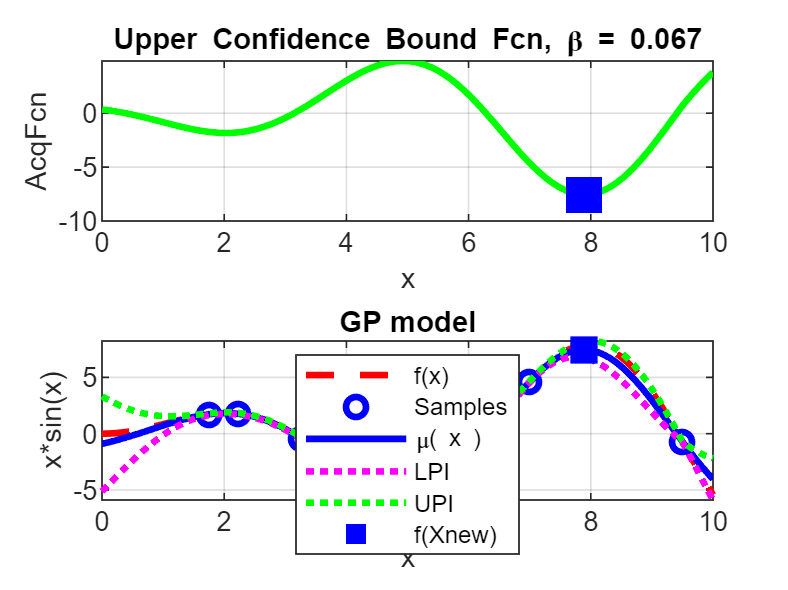

figure;
Xnew = B.Xnext;
subplot(2,1,1), plot( x, B.AcqObj.evalFcn( x ), 'g-', Xnew, B.AcqObj.evalFcn( Xnew ), 'bs', 'MarkerSize', 12,'LineWidth', 2, 'MarkerFaceColor','blue');
grid on
xlabel( "x" )
ylabel( "AcqFcn" )
Tstr = sprintf( "Upper Confidence Bound Fcn, \\beta = %4.3f", U.Beta );
title( Tstr ); 
subplot(2,1,2)
Xnew = B.Xnext;
Ynew = B.ModelObj.predict( Xnew );
B = B.addNewQuery( Xnew, Ynew );
plot(x, f, 'r--', X, Y, 'bo', x, Yp, 'b-', x, Yint( :,1 ), 'm:',...
    x, Yint( :,2 ), 'g:',  'LineWidth', 2);
hold on
plot( Xnew, Ynew, 'bs', 'MarkerSize', 10, 'MarkerFaceColor', 'blue');
grid on
legend( "f(x)", "Samples", "\mu( x )", "LPI", "UPI", "f(Xnew)", 'Location', 'north');
xlabel( "x" );
ylabel( "x*sin(x)" );
title( "GP model");